data = readtable("data_TPM.xlsx");
data = data(:, 2:end)

data = 26269×48 table
     BJ_Y1       BJ_Y2       BJ_Y3      BJ_OLD_1    BJ_OLD_2    BJ_OLD_3    IMR90_Y1    IMR90_Y2    IMR90_Y3    IMR90_O1    IMR90_O2    IMR90_O3    WI_38_Y1    WI_38_Y2    WI_38_Y3    WI_38_O1    WI_38_O2    WI_38_O3    HFF_PD16_1    HFF_PD16_2    HFF_PD16_3    HFF_PD74_1    HFF_PD74_2    HFF_PD74_3    MRC_5_PD32_1    MRC_5_PD32_2    MRC_5_PD32_3    MRC_5_PD72_1    MRC_5_PD72_2    MRC_5_PD72_3    HFF_PD26_1    HFF_PD26_2    

% Convertir la tabla a una matriz
dataMatrix = table2array(data);


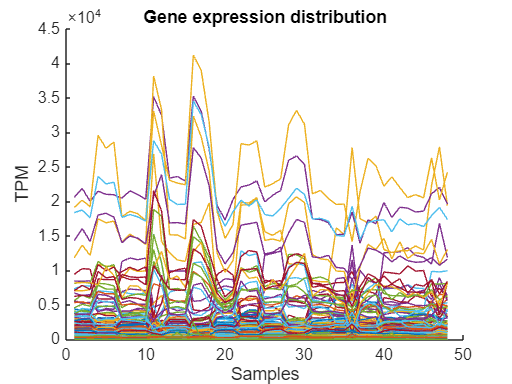

% Crear una nueva figura
figure;

% Mantener la gráfica para múltiples líneas
hold on;

% Obtener el número de filas y columnas de la matriz
[numRows, numCols] = size(dataMatrix);

% Iterar sobre cada fila de la matriz y plotearla
for i = 1:numRows
    plot(1:numCols, dataMatrix(i, :));
end

% Agregar títulos y etiquetas
title('Gene expression distribution');
xlabel('Samples');
ylabel('TPM');

% Mostrar la leyenda (opcional)
%legend(arrayfun(@(x) sprintf('Fila %d', x), 1:numRows, 'UniformOutput', false));

% Soltar la gráfica
hold off;